##  -- PART ONE --

*-- Bisection Method -- Secant Method -- Newton Method --*

# **BISECTION METHOD**

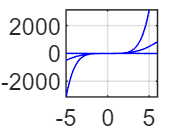

clear % CLEARING the momory before starting 

%------------STEP 1: Define the givens-------------

% -------from the user givens--------
% Here we define the function we are intending to solve
f = @(x) 4*(sin(x)) - 3 * (cos(x)); %example function 

% the interval [a, b] a is the lower bound and b is the upper
a = 0; %following the example
b = 1; %following the example
Err = 0.00001;

% -------pre-defined givens--------
c = (a+b)/2; %the assumed root (mid point of the interval)
iter = 0; % the number of iterations



%------------STEP 2: Graph the function-------------

figure(1)
fplot(f, [(a-5) (b+5)], 'b-') %increase the size of the integral to get a better look
grid on
hold on




%------------STEP 3: Iterattions loop-------------
format short 
% printing out first 'titles' row
fprintf(' n      a         b         c       f(a)      f(b)      f(c)     Error\n')

 n      a         b         c       f(a)      f(b)      f(c)     Error


while abs(a-b) > Err % it will keep looping till we reach the error
    iter = iter+1; % increment n in each iteration 
    fprintf('%2i %9.5f %9.5f %9.5f %9.5f %9.5f %9.5f %9.5f\n',iter, a,b,c,f(a),f(b),f(c),Err); % printing out each iteration
    if f(c) * f(a) > 0 % if f(a)nand f(b) has the sign, we will replace a with c
        a = c;
    else
        b = c; % otherwise we replace b with c. In order to proberly decrease the integral following Bisection method
    end 
    c = (a+b)/2; % update the value of c before going to the next iteration
end %loop ends here

 1   0.00000   1.00000   0.50000  -3.00000   1.74498  -0.71505   0.00001
 2   0.50000   1.00000   0.75000  -0.71505   1.74498   0.53149   0.00001
 3   0.50000   0.75000   0.62500  -0.71505   0.53149  -0.09250   0.00001
 4   0.62500   0.75000   0.68750  -0.09250   0.53149   0.21992   0.00001
 5   0.62500   0.68750   0.65625  -0.09250   0.21992   0.06374   0.00001
 6   0.62500   0.65625   0.64062  -0.09250   0.06374  -0.01438   0.00001
 7   0.64062   0.65625   0.64844  -0.01438   0.06374   0.02468   0.00001
 8   0.64062   0.64844   0.64453  -0.01438   0.02468   0.00515   0.00001
 9   0.64062   0.64453   0.64258  -0.01438   0.00515  -0.00461   0.00001
10   0.64258   0.64453   0.64355  -0.00461   0.00515   0.00027   0.00001
11   0.64258   0.64355   0.64307  -0.00461   0.00027  -0.00217   0.00001
12   0.64307   0.64355   0.64331  -0.00217   0.00027  -0.00095   0.00001
13   0.64331   0.64355   0.64343  -0.00095   0.00027  -0.00034   0.00001
14   0.64343   0.64355   0.64349  -0.00034   0.0002



%------------STEP 4: Printing out the output-------------

%since all iterations are in short format, we will print out the exact approximated answer
fprintf('\n--The approximated answer: %g\n', c)


--The approximated answer: 0.643497




clear % CLEARING the momory before starting

# **SECANT METHOD**

clear % CLEARING the momory before starting 

%------------STEP 1: Define the givens-------------

% -------from the user givens--------
% Here we define the function we are intending to solve
f = @(x) ((2)*x^3)+((2)*x^3)-(6); %example function 

x_n2 = 0;  % x_n-2 (value following the example)
x_n1 = 1; % x_n-1 (value following the example)
Err = 0.00000000000001; %the error

%fprintf('%g\n', x_n1, x_n2)

% -------pre-defined givens--------
iter = 1; % the number of iterations
x_n = 0; %to be calculated 


%------------STEP 2: Graph the function-------------

figure(1)
fplot(f, [(x_n2 - 5) (x_n1 + 5)], 'b-') %increase the size of to get a better look

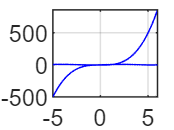

grid on
hold on




%------------STEP 3: Iterattions loop-------------
format short
%printing the first (titles) row 
fprintf(' n    x_n-2     x_n-1    f(x_n-2)  f(x_n-1)   x_n       Error\n')

 n    x_n-2     x_n-1    f(x_n-2)  f(x_n-1)   x_n       Error


while abs(x_n1 - x_n2) > Err % it will keep looping till we reach the error
    iter = iter+1; % increment n in each iteration

    x_n = x_n1 - ((f(x_n1) * (x_n1 - x_n2))/(f(x_n1) - f(x_n2))); %Secant method formula
    fprintf('%2i %9.5f %9.5f %9.5f %9.5f %9.5f %9.5f\n',iter,x_n2,x_n1,f(x_n2),f(x_n1),x_n,abs(x_n1-x_n2)); % printing out each iteration
    %updating variables
    x_n2 = x_n1;
    x_n1 = x_n;

end %loop ends here

 2   0.00000   1.00000  -6.00000  -2.00000   1.50000   1.00000
 3   1.00000   1.50000  -2.00000   7.50000   1.10526   0.50000
 4   1.50000   1.10526   7.50000  -0.59921   1.13447   0.39474
 5   1.10526   1.13447  -0.59921  -0.15969   1.14508   0.02920
 6   1.13447   1.14508  -0.15969   0.00572   1.14471   0.01061
 7   1.14508   1.14471   0.00572  -0.00005   1.14471   0.00037
 8   1.14471   1.14471  -0.00005  -0.00000   1.14471   0.00000
 9   1.14471   1.14471  -0.00000   0.00000   1.14471   0.00000




%------------STEP 4: Printing out the output-------------

%since all iterations are in short format, we will print out the exact approximated answer
fprintf('\n--The approximated answer: %g\n', x_n)


--The approximated answer: 1.14471




clear % CLEARING the momory before starting

# **NEWTON METHOD**

clear % CLEARING the momory before starting 

%------------STEP 1: Define the givens-------------

% -------from the user givens--------
% Here we define the function we are intending to solve
f = @(x) (x^5)+x-1;  %example function 
df = @(y) 5*(y^4)+1; %the derivative of the function 

x_n1 = 0; % x_n-1 (value following the example)
Err = 0.00000000000001; %the error

% -------pre-defined givens--------
iter = 0; % the number of iterations
x_n = 1; %to be calculated 



%------------STEP 2: Graph the function-------------

figure(1)
fplot(f, [(x_n1 - 5) (x_n1 + 5)], 'b-') %increase the size of to get a better look

grid on
hold on




%------------STEP 3: Iterattions loop-------------

format short
%printing the first (titles) row 
fprintf(' n    x_n-1    f(x_n-1)  f’(x_n-1)   x_n      Error\n')

 n    x_n-1    f(x_n-1)  f’(x_n-1)   x_n      Error


while abs(x_n1 - x_n) > Err % it will keep looping till we reach the error

    x_n1 = x_n; %updating the variable
    iter = iter+1; % increment n in each iteration

    x_n = x_n1 - (f(x_n1)/df(x_n1)); %Secant method formula
    fprintf('%2i %9.5f %9.5f %9.5f %9.5f %9.5f\n',iter,x_n1,f(x_n1),df(x_n1),x_n,abs(x_n1-x_n)); % printing out each iteration
    
end %loop ends here

 1   1.00000   1.00000   6.00000   0.83333   0.16667
 2   0.83333   0.23521   3.41127   0.76438   0.06895
 3   0.76438   0.02533   2.70692   0.75502   0.00936
 4   0.75502   0.00039   2.62486   0.75488   0.00015
 5   0.75488   0.00000   2.62359   0.75488   0.00000
 6   0.75488   0.00000   2.62359   0.75488   0.00000




%------------STEP 4: Printing out the output-------------

%since all iterations are in short format, we will print out the exact approximated answer
fprintf('\n--The approximated answer: %g\n', x_n)


--The approximated answer: 0.754878




clear % CLEARING the momory before starting